# **Cars Detection Project**

## **Section 1: Enhancing the video**

Enhance the video by removing the noise, convert the video to grayscale, then save the result as a new video file.

For an example frame, go from the noisy image (left) to the grayscale image (right).

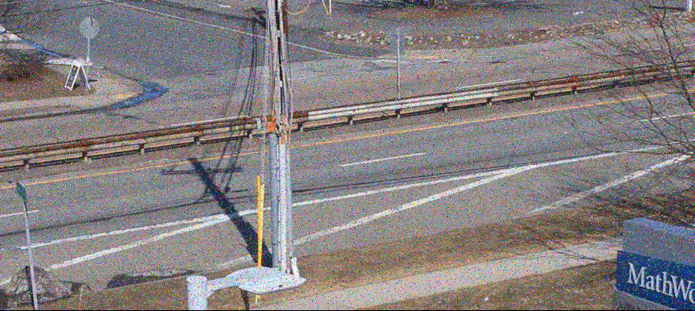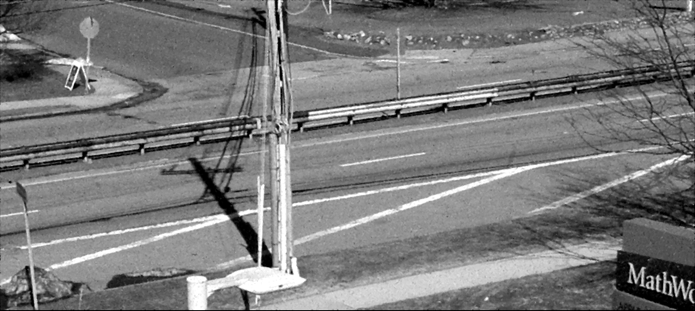

% Read the input video
v = VideoReader('RoadTraffic.mp4');

% Create a VideoWriter object for the output video
vOut = VideoWriter('CleanRoadTraffic.mp4', 'MPEG-4');
vOut.FrameRate = v.FrameRate;
open(vOut);

% Loop through each frame of the input video
while hasFrame(v)
    % Read a frame from the input video
    frame = readFrame(v);
    
    % Enhance the frame using the enhanceImage() function
    enhancedFrame = enhanceImage(frame);
    
    % Write the enhanced frame to the output video
    writeVideo(vOut, enhancedFrame);
end
% Close the VideoWriter object
close(vOut);


## Section 2.1: Isolating the cars with background subtraction

Isolate the cars using background subtraction.

The end goal of section 2 for an example frame, is to go from the grayscale image (left) to the BW mask image (right).

### Background subtraction preparation

First, create a background image with no cars from the first frame.

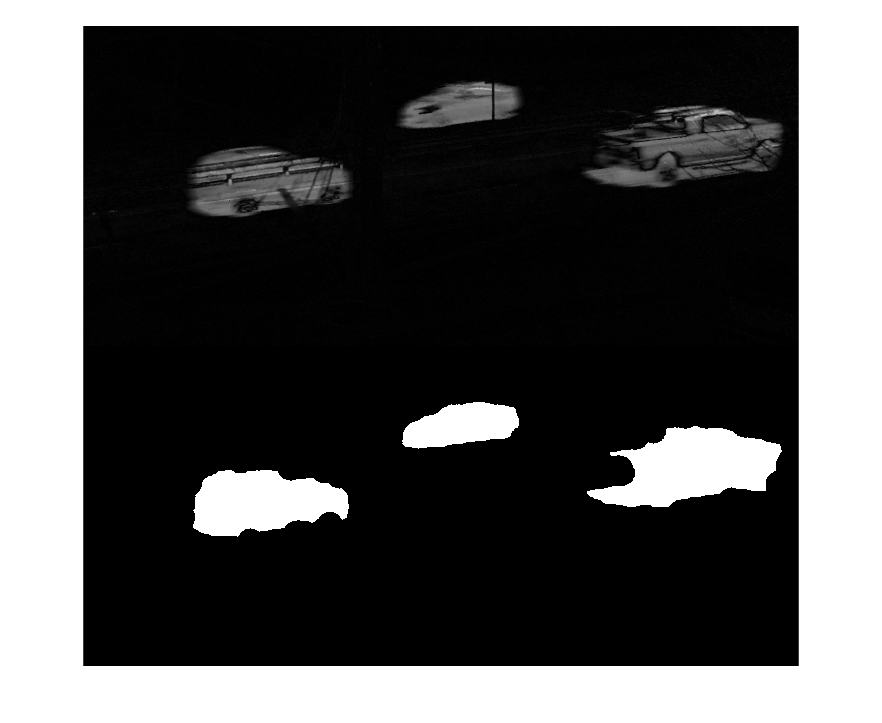

v= VideoReader("CleanRoadTraffic.mp4");
frameSum = im2double(read(v,1));
for idx = 2:v.NumFrames
    frameSum = frameSum + im2double(read(v,idx));
end
aveFrame = frameSum/ v.NumFrames;
% Test Frame Segmentation Algorithm
frame =read(v,153);
frame = im2double(frame);
background = aveFrame;
frameDiff = abs(frame - background);
[CarsBW,CarsMasked] = segmentedCars2(frameDiff);
montage({frameDiff,CarsBW})

CarsProps = regionprops("table",CarsBW,"all");
CarsProps

CarsProps = 3×30 table
    Area         Centroid                  BoundingBox                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        

totalTruePixels = sum(CarsBW(:));

## Sections 2.2 & 3: Segmenting cars and Calculating region properties

Segment the cars and create a table that contains a row for each frame of the video and a column for the following three properties: number of regions, mean region size, and total region size.

% Initialize the video reader object.
v= VideoReader("CleanRoadTraffic.mp4");
frameSum = im2double(read(v,1));
for idx = 2:v.NumFrames
    frameSum = frameSum + im2double(read(v,idx));
end
aveFrame = frameSum/ v.NumFrames;
imshow(aveFrame)

% Get the total number of frames in the video
numFrames = v.NumFrames;

% Create a table to store the region information
regionTable = table();

% Initialize variables for average region size calculation
totalRegionSize = 0;
numFramesWithCar = 0;

% Process each frame
for frameNumber = 1:numFrames
    % Read the current frame
    frame = read(v, frameNumber);
    
    % Convert the frame to double precision
    frame = im2double(frame);
    
    % Calculate frame difference
    frameDiff = abs(frame - aveFrame);
  
    % Segment the cars using the segmentedCars2() function
    [CarsBW, ~] = segmentedCars2(frameDiff);
    
    % Calculate region properties
    CarsProps = regionprops(CarsBW, 'Area');
    
    % Check if at least one car is detected in the frame
    if ~isempty(CarsProps)
        % Update region size and frame count
        totalRegionSize = totalRegionSize + sum([CarsProps.Area]);
        numFramesWithCar = numFramesWithCar + 1;
    end
    
    % Create a row for the current frame in the region table
    frameRow = table(frameNumber, size(CarsProps, 1), mean([CarsProps.Area]), sum([CarsProps.Area]));
    
    % Append the frame row to the region table
    regionTable = [regionTable; frameRow];
end

% Calculate the average region size in terms of pixels
averageRegionSize = totalRegionSize / numFramesWithCar;

% Display the region table
disp(regionTable);

    frameNumber    Var2     Var3     Var4 
    ___________    ____    ______    _____

          1         0         NaN        0
          2         0         NaN        0
          3         0         NaN        0
          4         0         NaN        0
          5         1          73       73
          6         2        3132     6264
          7         2       10186    20372
          8         2       15974    31949
          9         2       15258    30515
         10         2       13942    27883
         11         2       13329    26658
         12         2       14908    29817
         13         2       14368    28735
         14         2       13739    27478
         15         4        6493    25972
         16         3       12458    37373
         17         3       16533    49599
         18         2       23313    46626
   

% Display the average region size
disp("Average region size (pixels): " + averageRegionSize);

Average region size (pixels): 18500.0621


%% Moving Car Detection Project
% Task is to finding moving cars, and insert a bounding box around it

v = VideoReader("NewRoadTraffic.mp4");
v.FrameRate;
firstFrame = read(v,1);
firstFrame = im2double(firstFrame);

v2 = VideoWriter("car_bound2.mp4", "MPEG-4");
v2.FrameRate = v.FrameRate;
open(v2)

for idx = 1:v.NumFrames
    frame = read(v,idx);
    frame = im2double(frame);

    frameDiffer = abs (firstFrame - frame);

    bw = segmentedCars2(frameDiffer);

    props = regionprops("table",bw,"BoundingBox");

    carboxed = insertShape(frame,"rectangle",props.BoundingBox,...
        "LineWidth",3,"Color","red");
    writeVideo(v2,carboxed)
end
close(v2);


% Create VideoReader objects for both videos
video1Reader = VideoReader("RoadTraffic.mp4");
video2Reader = VideoReader("car_bound2.mp4");

% Get video properties
frameRate = video1Reader.FrameRate;
frameWidth = video1Reader.Width;
frameHeight = video1Reader.Height;

% Create a new VideoWriter object for the output montage video
outputVideo = VideoWriter("ComparisonRoadTraffic.mp4", 'MPEG-4');
outputVideo.FrameRate = frameRate;
open(outputVideo);

% Read and process each frame from both videos
while hasFrame(video1Reader) && hasFrame(video2Reader)
    % Read frames from both videos
    frame1 = readFrame(video1Reader);
    frame2 = readFrame(video2Reader);

    % Resize frame 2 to match frame 1's height 
    frame2 = imresize(frame2, [frameHeight, NaN]);

    % Create a new frame with both videos side by side
    montageFrame = [frame1, frame2];

    % Write the frame into the output video
    writeVideo(outputVideo, montageFrame);
end

% Close the output video file
close(outputVideo);


## Segmentation function

function [BW,maskedImage] = segmentedCars2(X)
%segmentImage Segment image using auto-generated code from Image Segmenter app
%  [BW,MASKEDIMAGE] = segmentImage(X) segments image X using auto-generated
%  code from the Image Segmenter app. The final segmentation is returned in
%  BW, and a masked image is returned in MASKEDIMAGE.

% Auto-generated by imageSegmenter app on 18-Jul-2023
%----------------------------------------------------

% Threshold image with manual threshold
BW = im2gray(X) > 2.000000e-01;

% Open mask with disk
radius = 3;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imopen(BW, se);

% Close mask with disk
radius = 20;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imclose(BW, se);

% Create masked image.
maskedImage = X;
maskedImage(~BW) = 0;

end
